Kattints az út rajzolásához! Nyomj ENTER-t a záráshoz.
Számolás: Pálya generálás...
Figyelem: Legalább 3 pont kell!


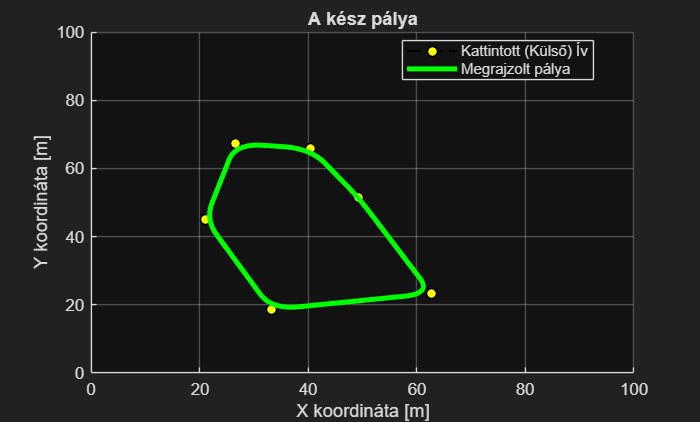

%% ============================================================
%  MAIN SCRIPT
%  ------------------------------------------------------------
%  Project name   : Tube MPC optimization with neural network
%  Author         : Bene Ádám
%  Date           : 2026.04.28.
%  Description    : Main execution script that calls the
%                   required submodules and processing steps.
%
%  Note           : Run this file directly.
%% ============================================================

% reference path define for the controller
run("path_define.mlx")

=== 2. FÁZIS: CasADi MPC Szimuláció és Adatgyűjtés ===
CasADi szimuláció fut... (az IPOPT megoldó dolgozik)
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  19.00us (  2.71us)         7
       nlp_g  |        0 (       0)  46.00us (  6.57us)         7
  nlp_grad_f  |        0 (       0)  26.00us (  3.25us)         8
  nlp_hess_l  |        0 (       0)  13.00us (  2.17us)         6
   nlp_jac_g  |        0 (       0)  28.00us (  3.50us)         8
       total  |   1.55 s (  1.55 s)   1.55 s (  1.55 s)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  21.00us (  3.00us)         7
       nlp_g  |        0 (       0)  54.00us (  7.71us)         7
  nlp_grad_f  |        0 (       0)  31.00us (  3.87us)         8
  nlp_hess_l  |   1.00ms (166.67us)  19.00us (  3.17us)         6
   nlp_jac_g  |        0 (       0)  36.00us (  4.50us)         8
       total  |  29.00ms ( 29.00ms

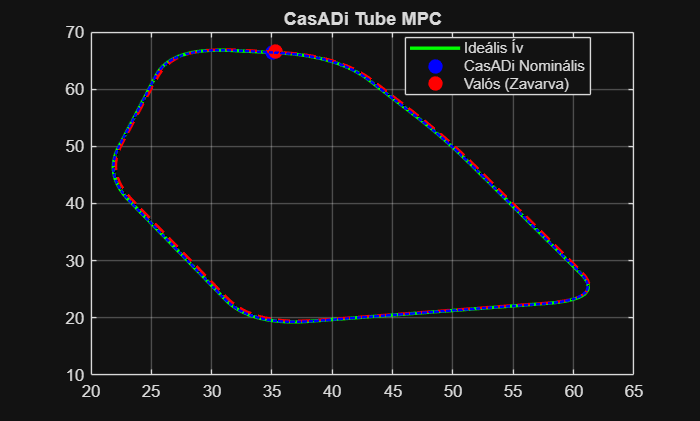


% run tube MPC for previously defined reference path
run("tube_mpc.mlx")

=== Neurális Háló Tanítása Indul ===


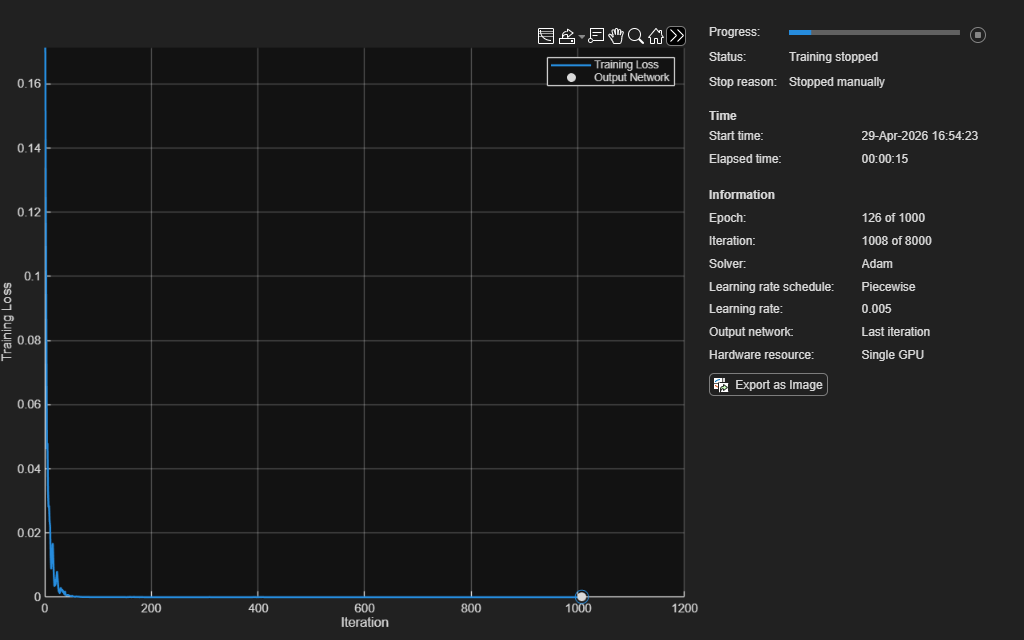

=== TANÍTÁS BEFEJEZŐDÖTT! A "net" nevű objektum elkészült. ===
--- Tesztelés az első időlépésen ---
Valós maradék hiba (a szimulációdból):
         0         0    0.1112    0.0687

Neurális háló által becsült hiba:
    0.0011    0.0013    0.1029    0.0723




% train the NN from the offline data of the previous simulation
run("train_nn.mlx")